dipstart


DIPlib 2.9 (Oct 17 2017 - Release [on Cygwin (with OpenMP)])
    Scientific Image Analysis Library
    Quantitative Imaging Group, Delft University of Technology 1995-2017
    info@diplib.org


dipIO 2.9 (Oct 17 2017 - Release)
    File I/O library for DIPlib
    Quantitative Imaging Group, Delft University of Technology 1999-2017
    info@diplib.org



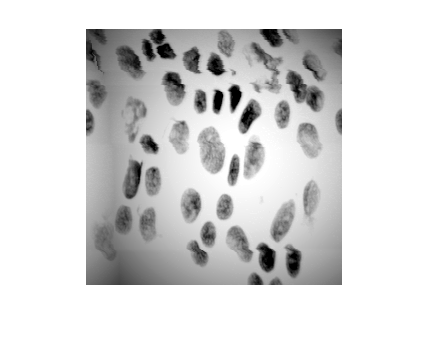

a = imread('qdna1.tif');
imshow(a)

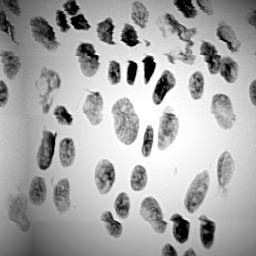

Displayed in figure 13


a - laplace(a)

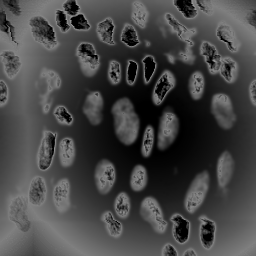

Displayed in figure 14


2*a - gaussf(a)

Q1: for Part 5 (un)sharpening: The two (un)sharping filters (“a-laplace(a)” and “2*a - gaussf(a)”) are not the same. Can you explain the difference of them? How are they alike?

Ans: the "a-laplace(a)" means the original image minus the Laplace of the image, the "2*a - gaussf(a)" means we remain the low-frequency components and double the high-frequency components of the image. Both methods will sharpen the image. 

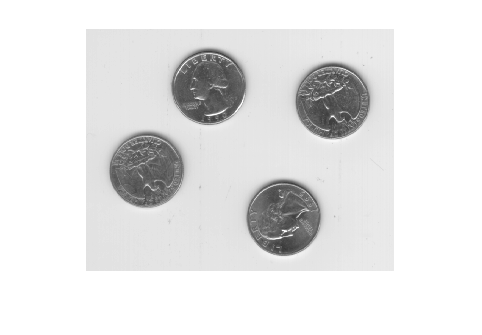

I = imread('eight.tif');
figure
imshow(I)

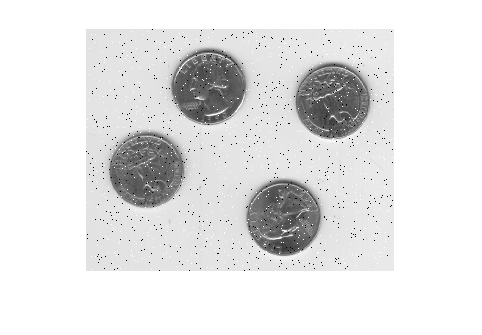

J = imnoise(I,'salt & pepper',0.02);
figure
imshow(J)

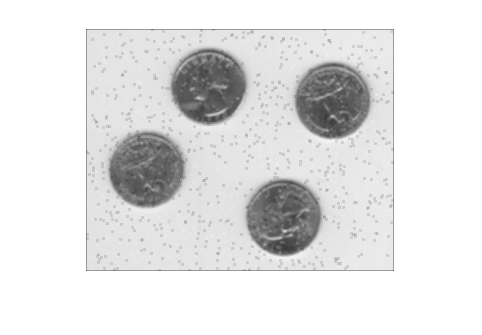

Kaverage = filter2(fspecial('average',3),J)/255;
figure
imshow(Kaverage)

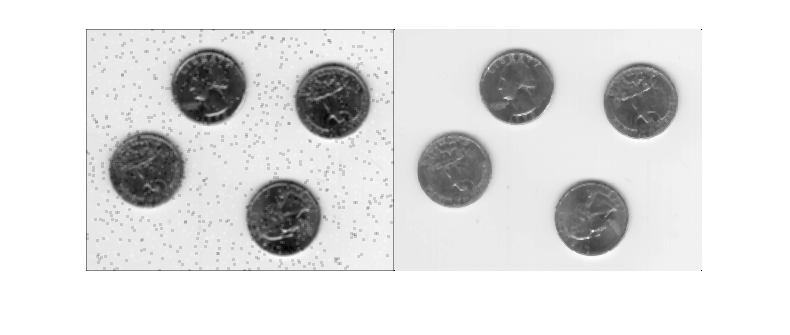

Kmedian = medfilt2(J);
imshowpair(Kaverage,Kmedian,'montage')

Q2: Try out the above example and understand it. 

Goal: Make your own applications and demo for image filtering part. 

Requirements:

•	you choose at least 2 applications: (un)sharpening, smoothing, blurring, noise reduction 

Ans: 

• (un)sharpening: I use function imsharpen with Radius = 2 (the value is the size of the region around the edge pixels that is affected by sharpening), Amount = 2 (how strong the filter effect is going to be). 

• Noise reduction: First I added salt and pepper into the original image by using function imnoise, the I use the Median filter. The filter would take each pixel of the image then transform it into a pixel with 3-by-3 neighborhood around the pixel with median value, resulting an image with random salt and pepper removed.  

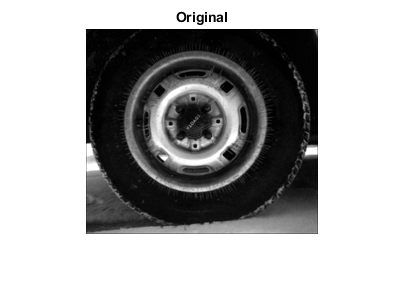

MyImage = imread('tire.tif');
imshow(MyImage),title('Original')

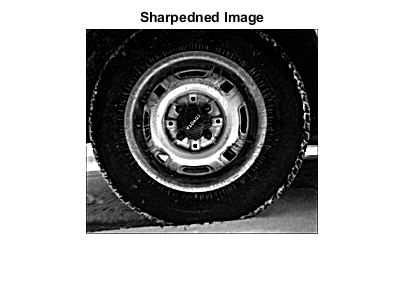

Sharpened = imsharpen(MyImage,'Radius',2,'Amount',2);
imshow(Sharpened), title('Sharpedned Image')

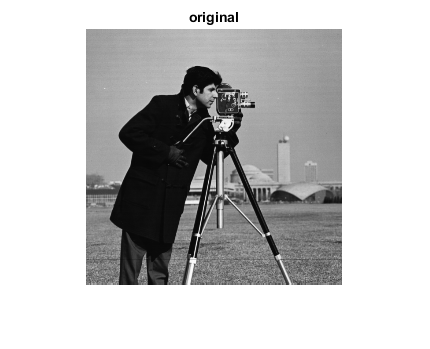

MyImage = imread('cameraman.tif');
imshow(MyImage),title('original')

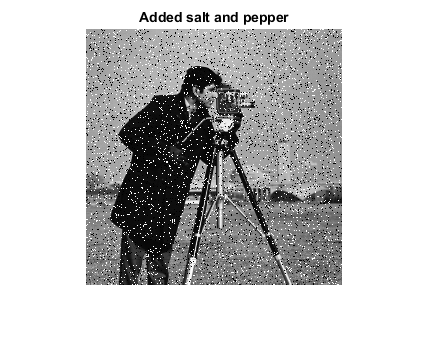

Kaverage = imnoise(MyImage,'salt & pepper',0.1);
imshow(Kaverage), title('Added salt and pepper')

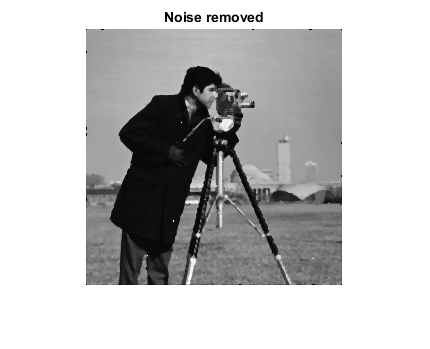

NoiseReduced = medfilt2(Kaverage);
imshow(NoiseReduced), title('Noise removed')

Q3: you choose at least 2 applications and implement them in matlab. 

Ans:

•  **Application Goal: edge detection: **I use Prewitt method to detect the edges of the object in the image. The method calculates the gradient of the image intensity at each point, giving the direction of the largest possible increase from light to dark and the rate of change in that direction, resulting the represented edges of the image. 

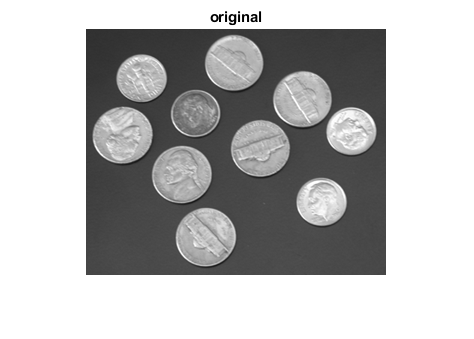

Image1 = imread('coins.png');
imshow(Image1), title('original')

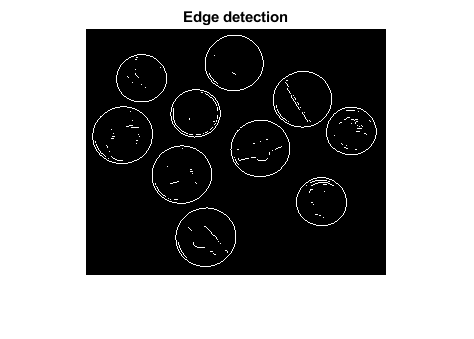

Edge = edge(Image1,'Prewitt');
imshow(Edge),title('Edge detection')

•  **Application Goal: image thresholding: **I use function multithresh to calculate 2 threshold levels of the original image, then I seperate it into 3 levels using function imquantize. Finally I convert it into color image using function label2rgb 

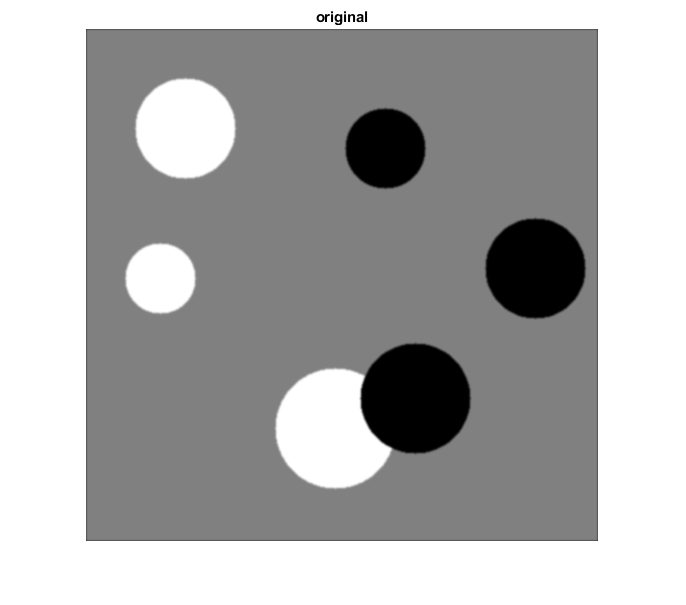

Image2 = imread('circlesBrightDark.png');
imshow(Image2), title('original')

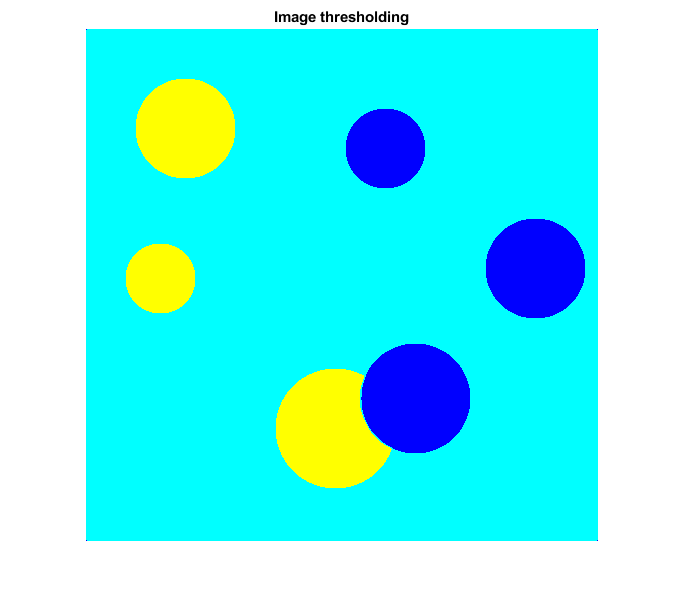

Threshold = multithresh(Image2, 2);
Segment = imquantize(Image2,Threshold);
RGB = label2rgb(Segment);	
imshow(RGB),title('Image thresholding')